**Laboratorium 11 – Filtracja Sygnałów, filtry IIR**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Zadanie 1

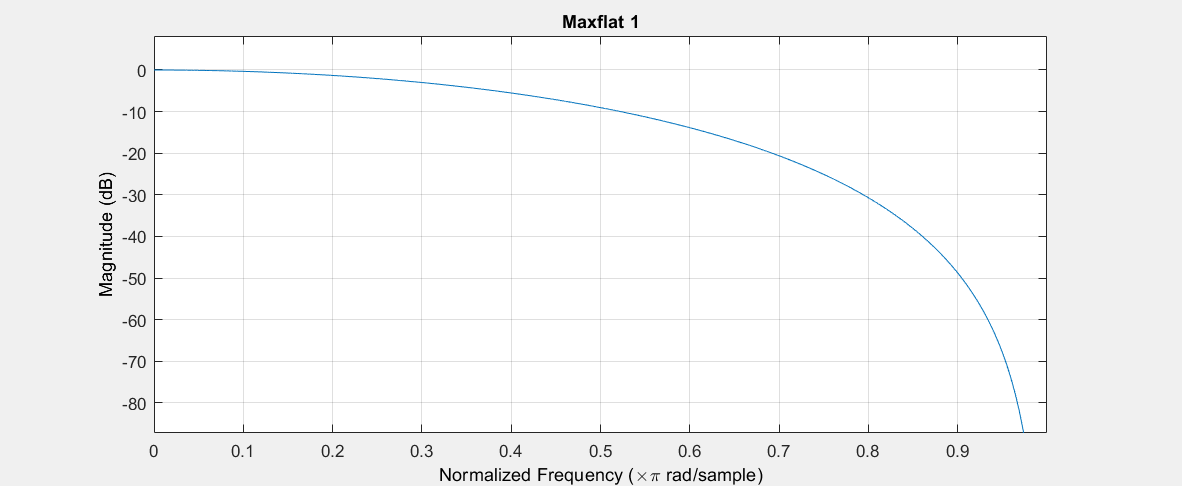

clear all, close all, clear variables
figure
[b,a] = maxflat(4,1,0.3);
fvtool(b,a);
title('Maxflat 1');

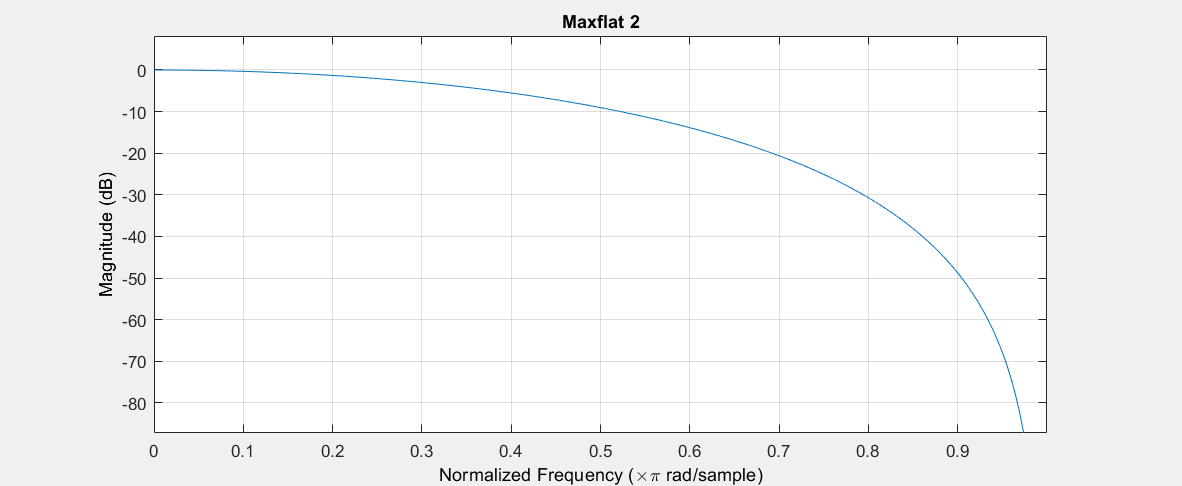


maxflat(4,'sym',0.3);
fvtool(b,a);
title('Maxflat 2');

Zadanie 2

clear all, close all, clear variables
figure
b = [1 -0.5]; 
a = [1 -2];
act_flag2 = isstable(b,a)

act_flag2 = logical
   0


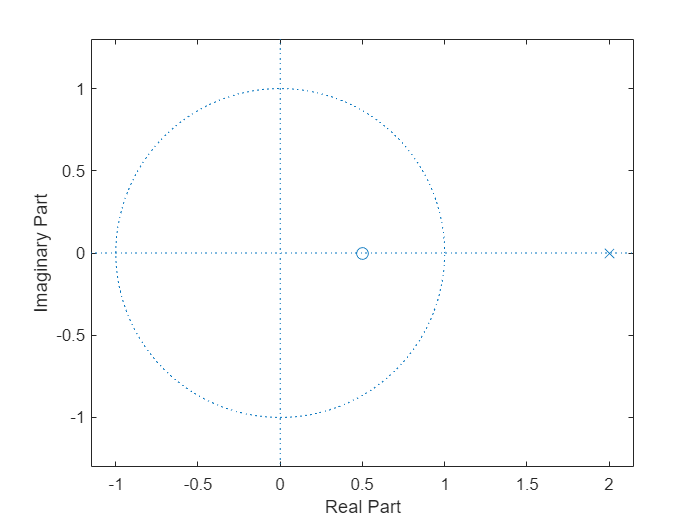

zplane(b,a)

Filtr jest niestabilny, ponieważ x znajduje się poza kołem.

Zadanie 3

clear all, close all, clear variables
figure
b = [1 -0.1]; 
a = [-1 -0.1];
act_flag3 = isstable(b,a)

act_flag3 = logical
   1


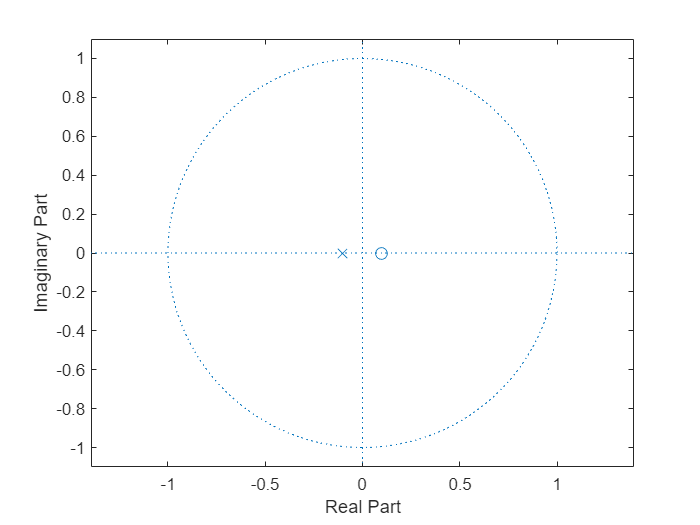

zplane(b,a)

Filtr jest stabilny, ponieważ x znajduje się w kole.

Zadanie 4

clear all, close all, clear variables
figure
b = [0.9 -0.8]; 
a = [-0.9 -0.8];
act_flag4 = isstable(b,a)

act_flag4 = logical
   1


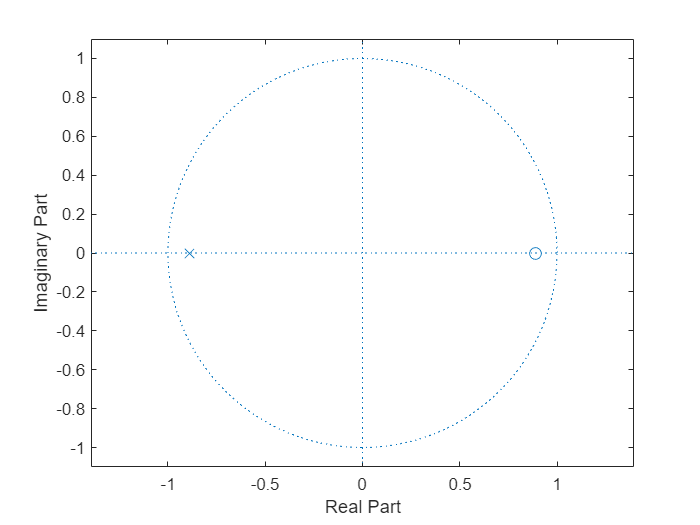

zplane(b,a)

Filtr jest stabilny, ponieważ x znajduje się w kole.

Zadanie 5

clear all, close all, clear variables
figure
b = [0.9 -0.8 1 1]; 
a = [-0.9 -0.8 -1];
act_flag5 = isstable(b,a)

act_flag5 = logical
   0


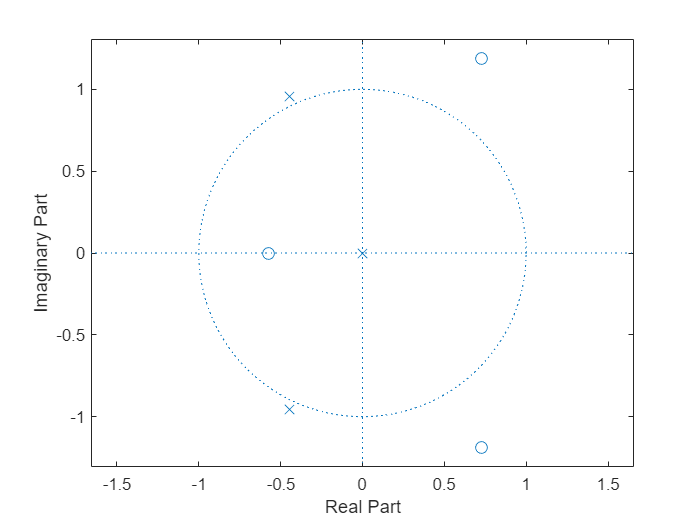

zplane(b,a)

Filtr jest niestabilny, ponieważ część x nie znajduje się w kole.

Zadanie 6

clear all, close all, clear variables
figure
m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
act_flag6 = isstable(b, a)

act_flag6 = logical
   1


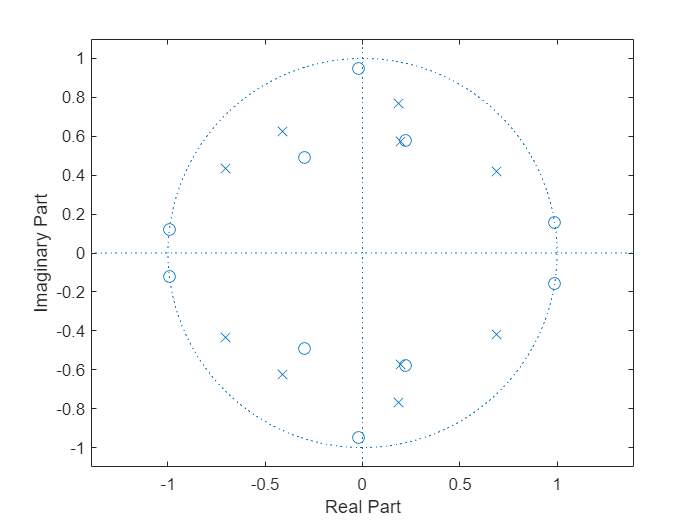

zplane(b, a);

Filtr jest stabilny, ponieważ każdy x jest w kole.

Zadanie 7

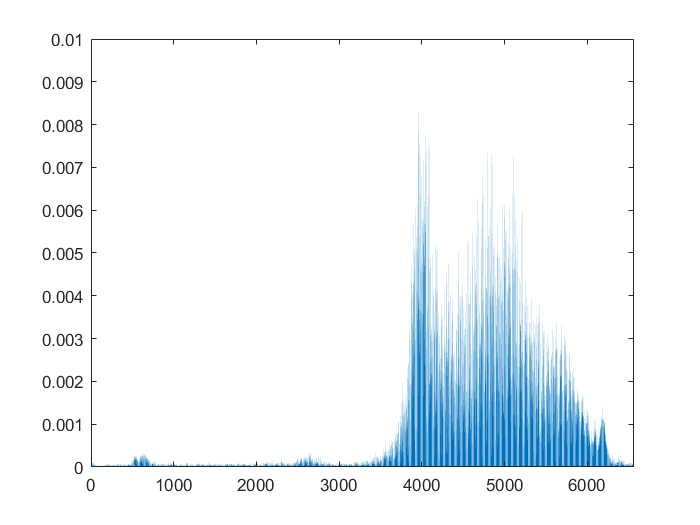

clear all, close all, clear variables
figure
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

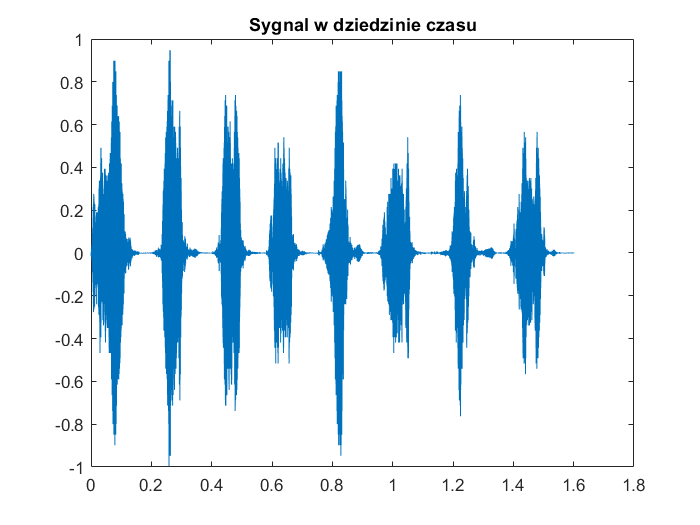

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

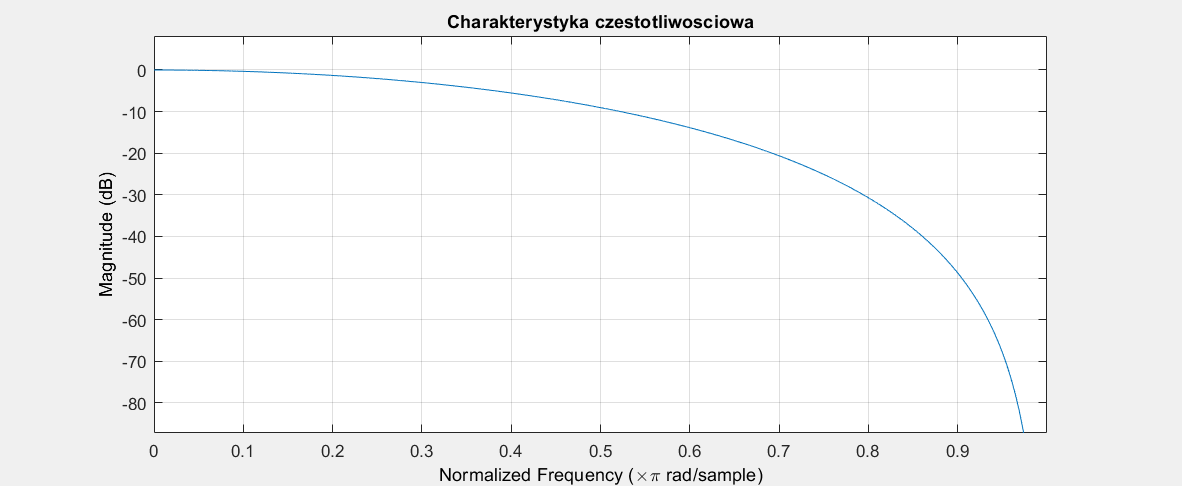


[b,a] = maxflat(4, 1, 0.3);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

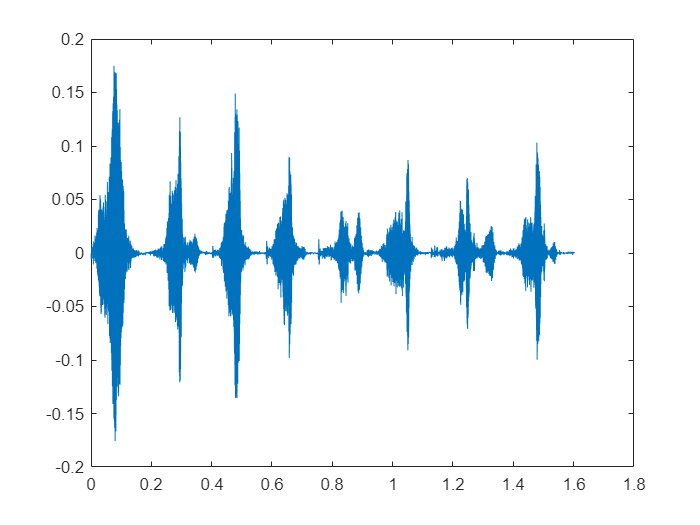


outsignal = filter(b,a,y);
plot(t, outsignal);

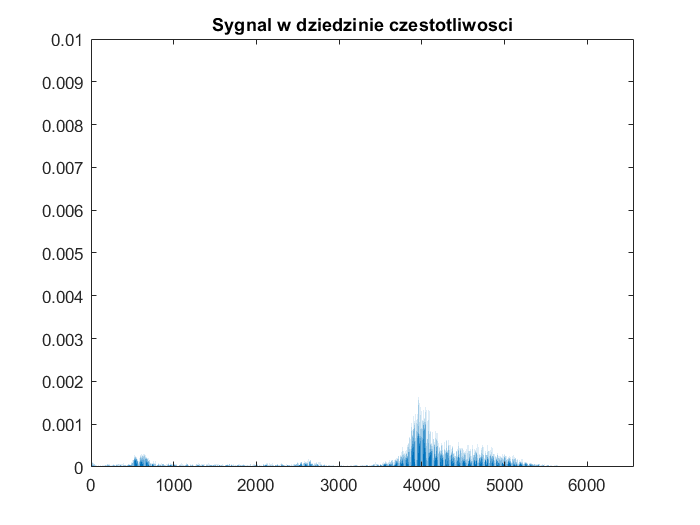

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 8

clear all, close all, clear variables
figure
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

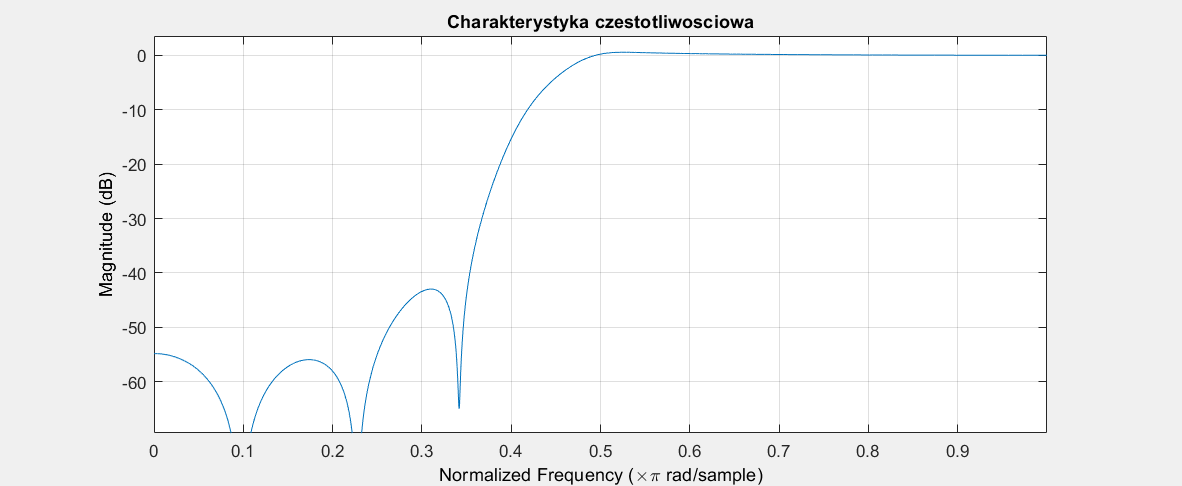


m = [0 0 0 0 0 1 1 1 1 1];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

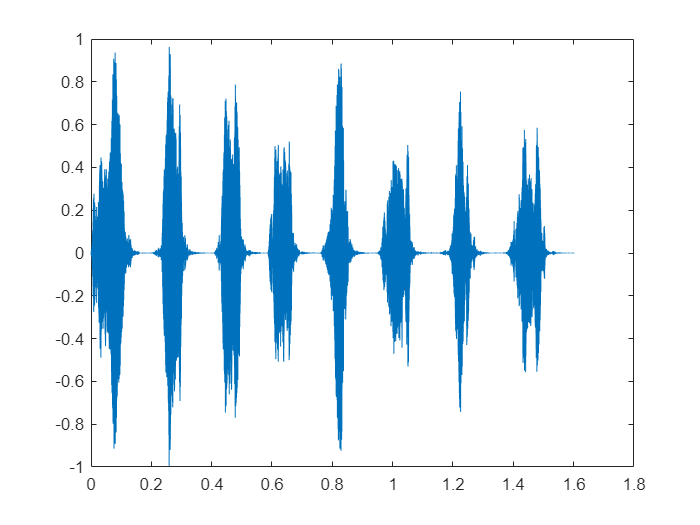


outsignal = filter(b,a,y);
plot(t, outsignal);

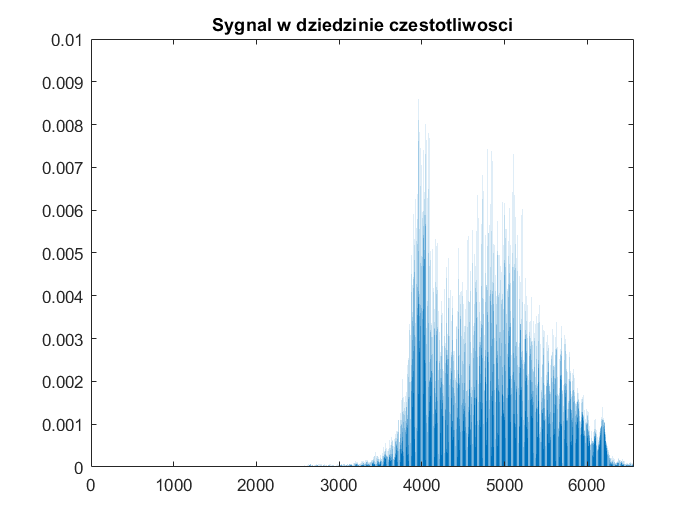

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 9

clear all, close all, clear variables
figure
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

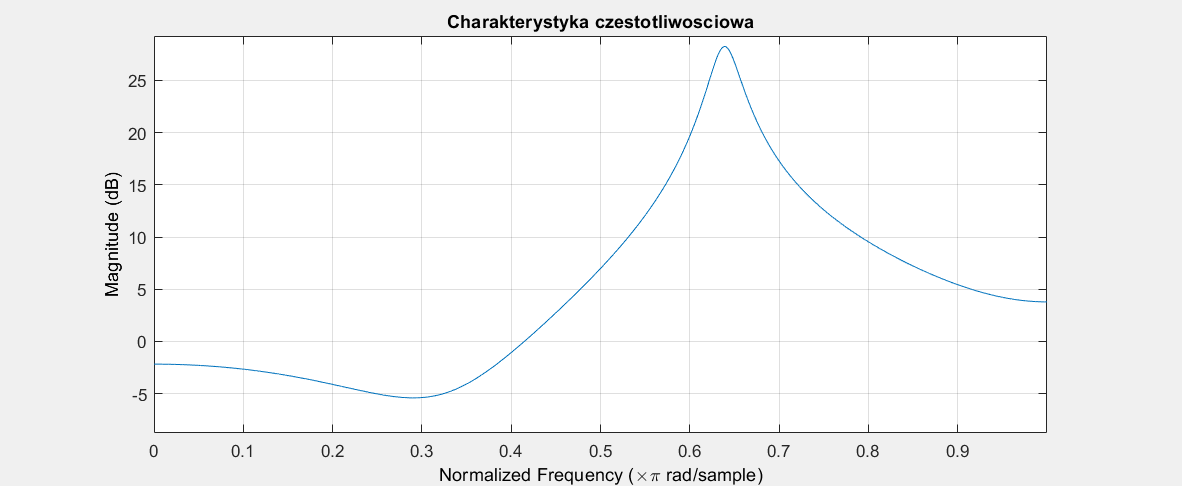


b = [0.9 -0.8 1 1]; 
a = [-0.9 -0.8 -1]; 
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

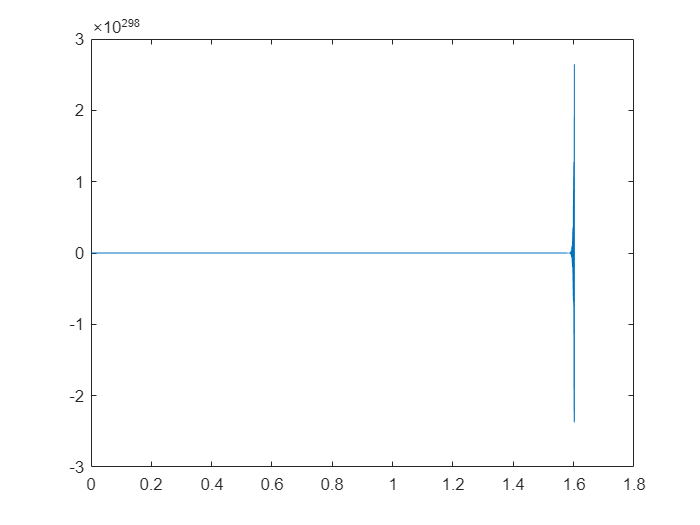


outsignal = filter(b,a,y);
plot(t, outsignal);

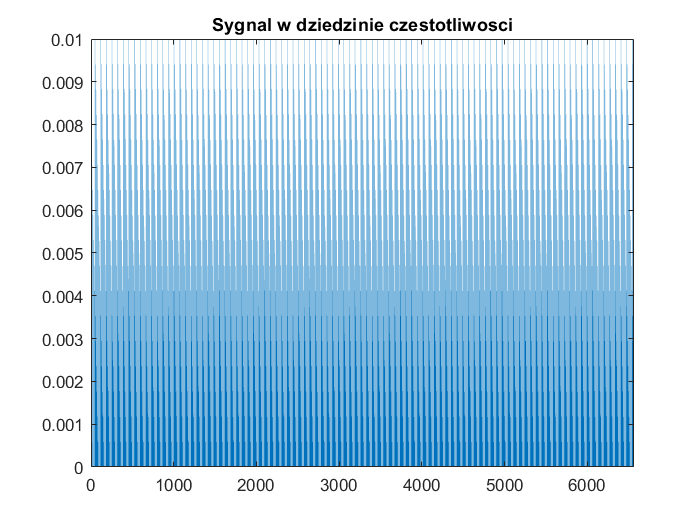

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 10

clear all, close all, clear variables
figure
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

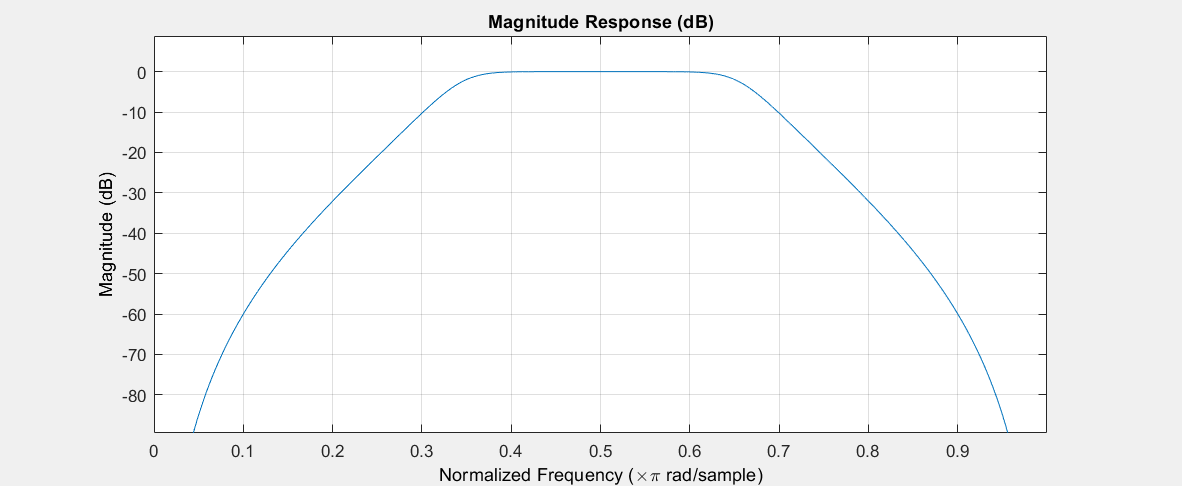


[n,Wn] = buttord([2000 3000]/5000,[500 4500]/5000,1,60) ;
[b,a] = butter(n,Wn);
fvtool(b,a)

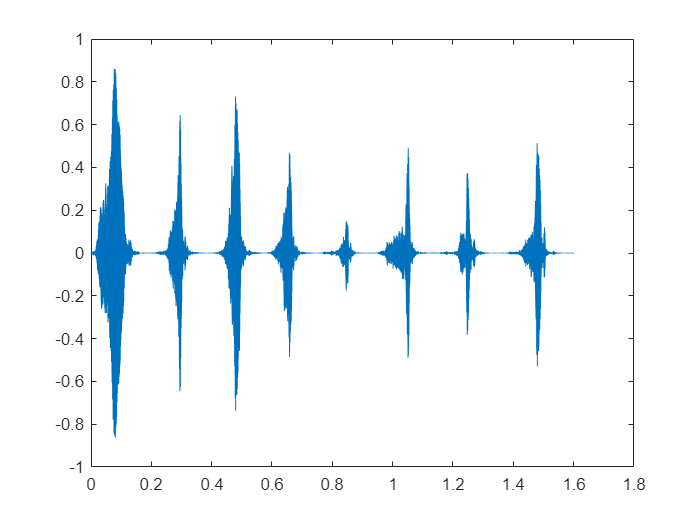


outsignal = filter(b,a,y);
plot(t, outsignal);

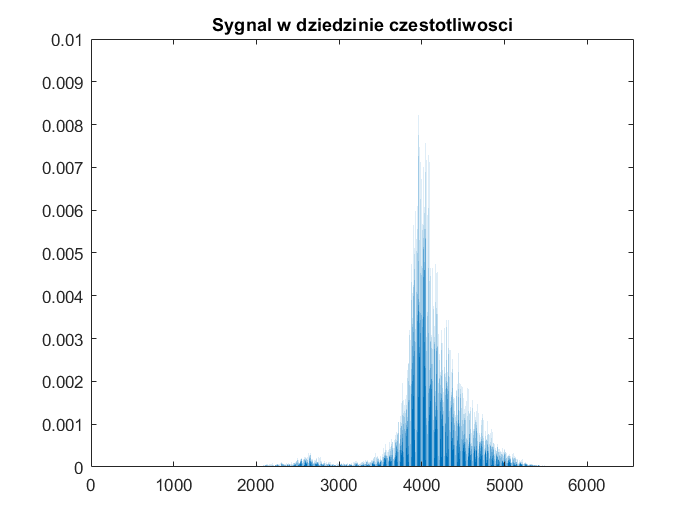

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 11

clear all, close all, clear variables
figure
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

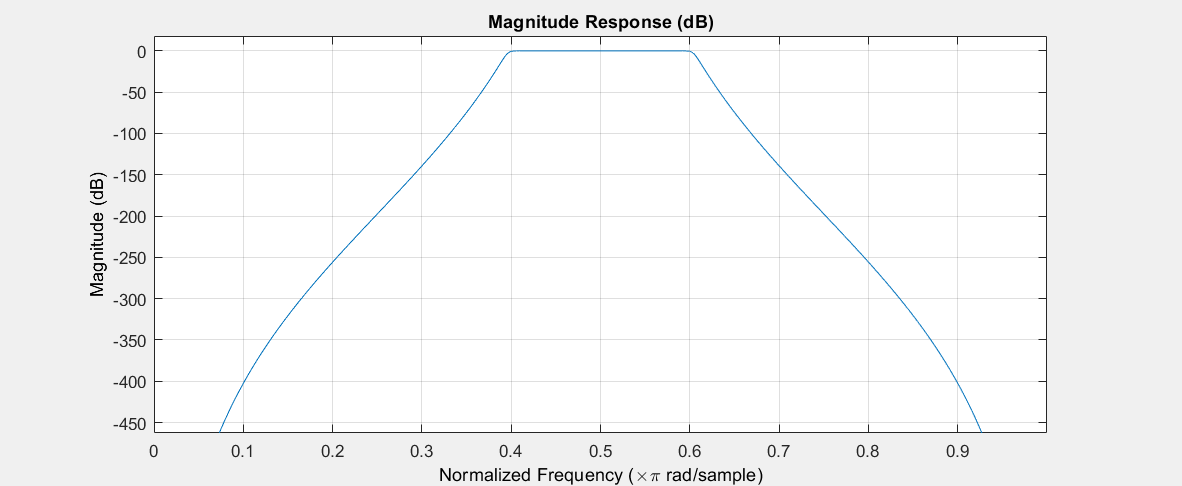


[n,Wn] = buttord([2000 3000]/5000,[1800 3200]/5000,1,60);
[b,a] = butter(n,Wn);
fvtool(b,a)

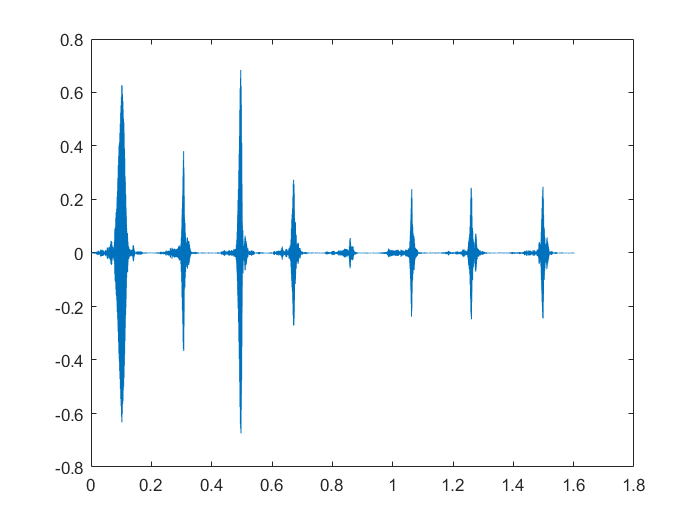


outsignal = filter(b,a,y);
plot(t, outsignal);

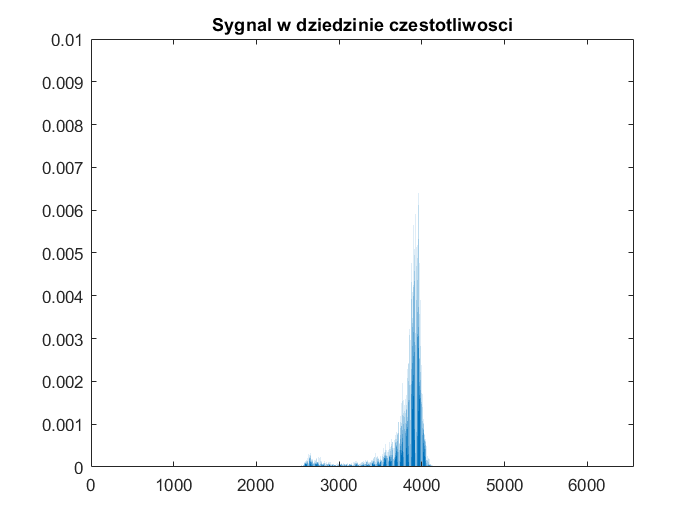

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 12

clear all, close all, clear variables
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

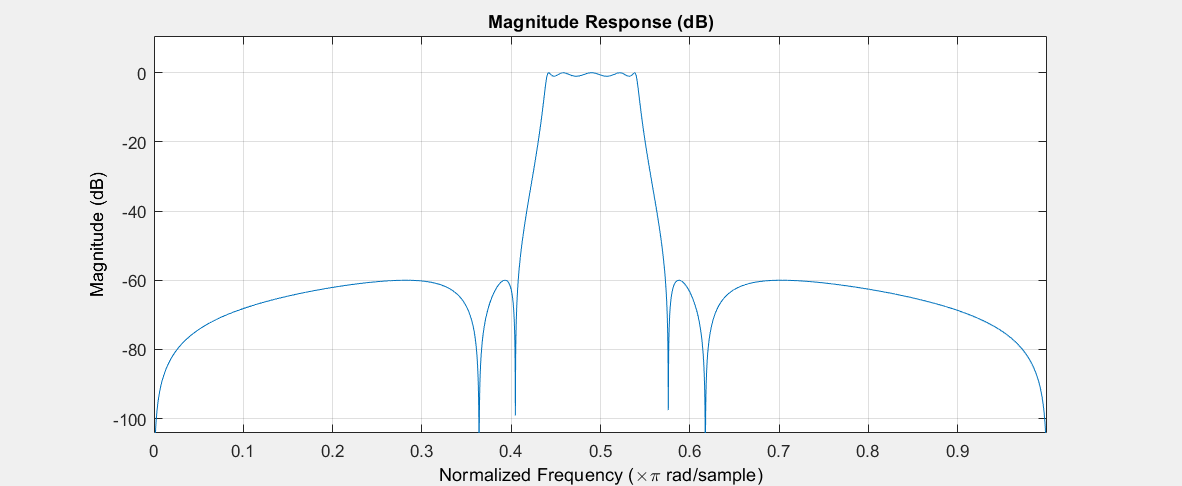


[n,Wn] = ellipord([2200 2700]/5000,[2000 2900]/5000,1,60);
[b,a] = ellip(n,1,60,Wn);
fvtool(b,a)

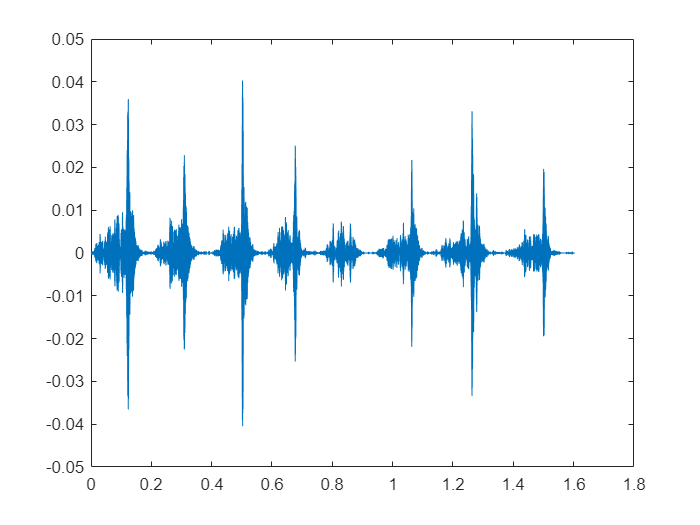


outsignal = filter(b,a,y);
plot(t, outsignal);

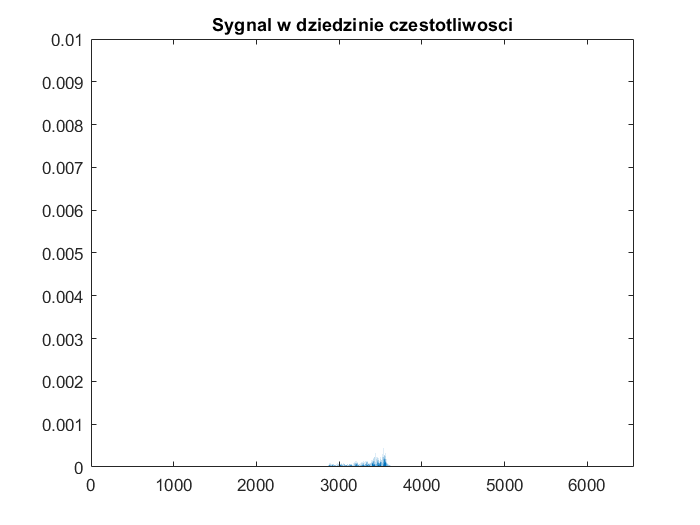

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 13

clear all, close all, clear variables
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

figure
plot(t,y);
title('Sygnal w dziedzinie czasu');

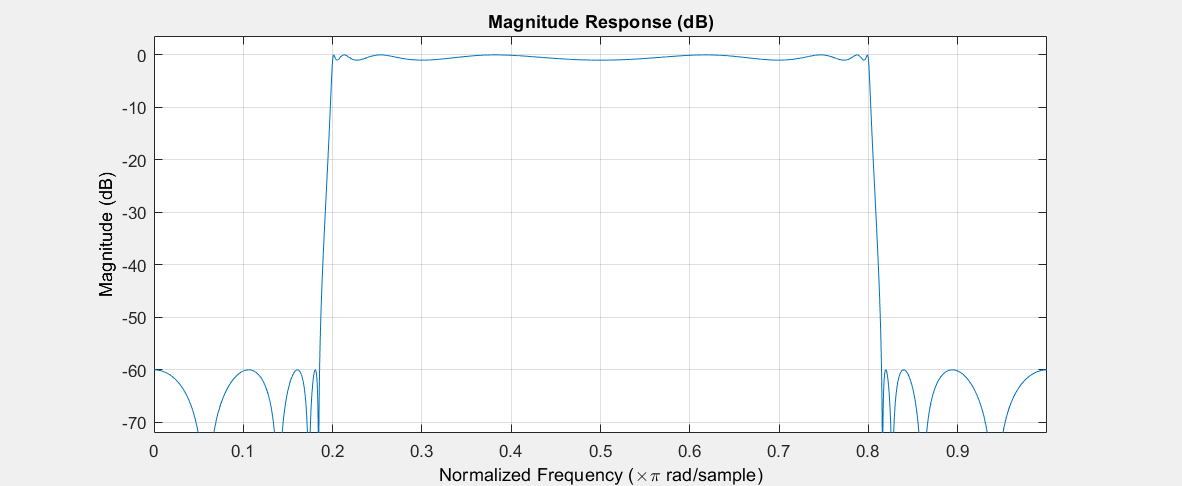


[n,Wn] = ellipord([1000 4000]/5000,[900 4100]/5000,1,60);
[b,a] = ellip(n,1,60,Wn);
fvtool(b,a)

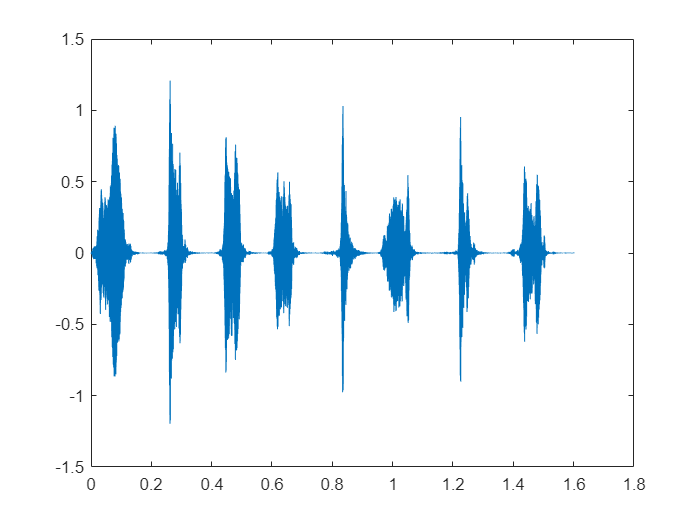


outsignal = filter(b,a,y);
plot(t, outsignal);

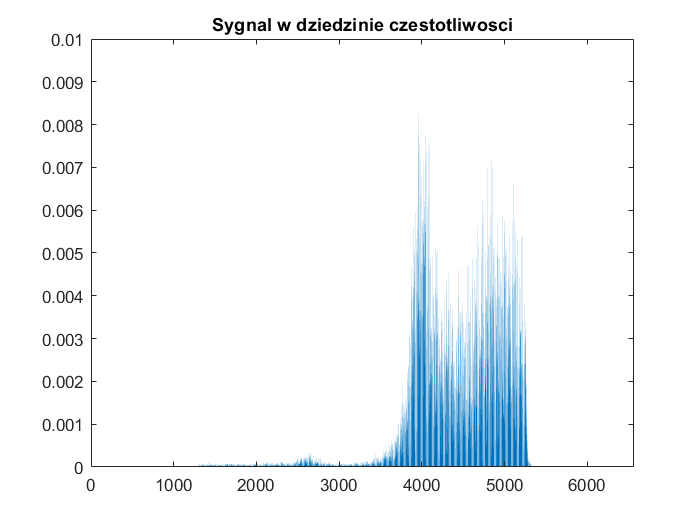

xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

Zadanie 14

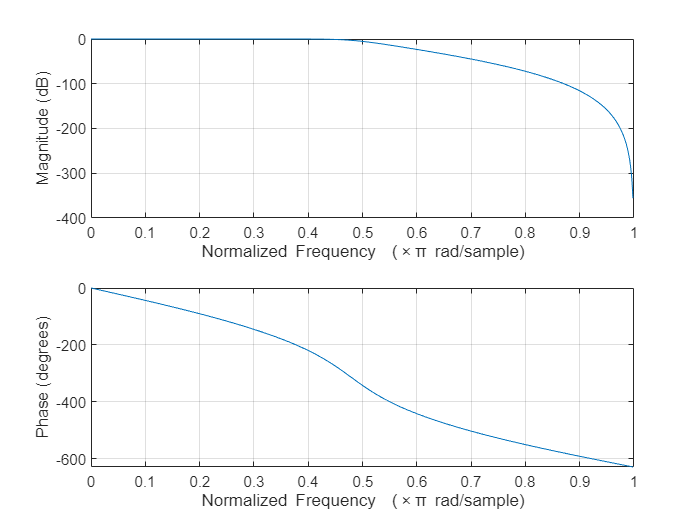

clear all, close all, clear variables

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
[zhi,phi,khi] = butter(7,0.48,'low');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)
outhi = sosfilt(soshi,y);
subplot(2,1,1)

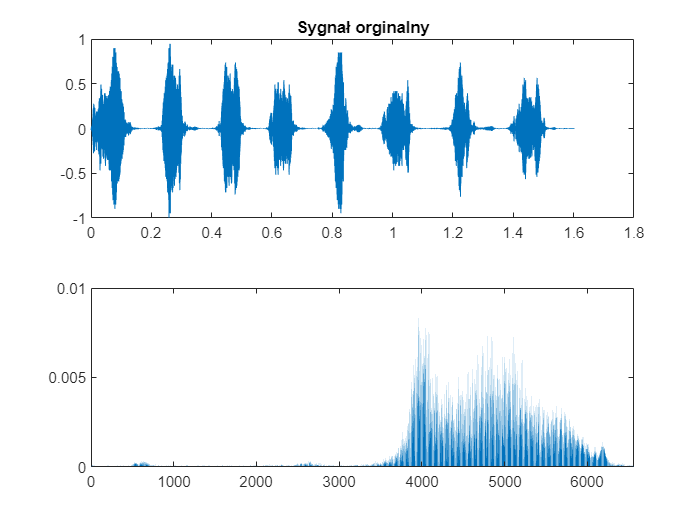

plot(t,y)
title('Sygnał orginalny')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal')
xlabel('Czas [s]')
ylim(ys)
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

Zadanie 15

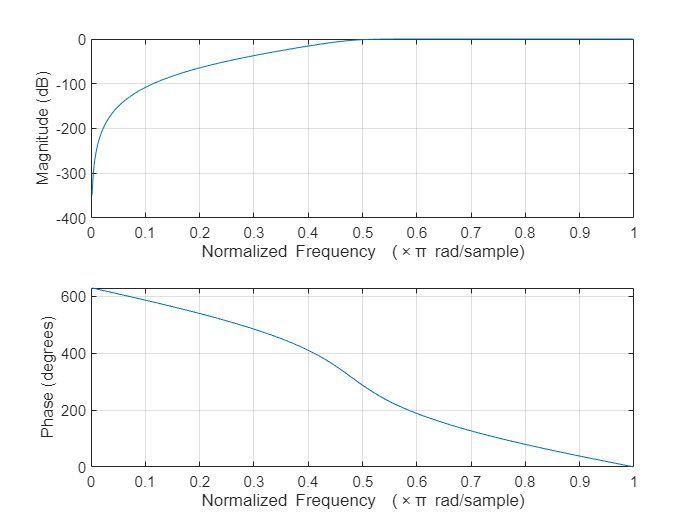

clear all, close all, clear variables
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
[zhi,phi,khi] = butter(7,0.48,'high');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)
outhi = sosfilt(soshi,y);
subplot(2,1,1)

plot(t,y)
title('Sygnał orginalny')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Lowpass-Filtered Signal')
xlabel('Czas [s]')
ylim(ys)
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

**Pytania**

**1. Informacje na temat w jaki sposób projektujemy filtry IIR. **

Filtry IIR są trudniejsze w projektowaniu od filtrow FIR. Obecnie do projektowania filtru używa sie komputera i odpowiedniego oprogramowania (np Matlab).

**2. Różnice między filtrami FIR i IIR.**

Filtry FIR zapewniają nam stabilność, liniowość fazy, sa łatwe w projektowaniu. Są jednak bardziej obciążające obliczeniowo. Natomiast filtry IIR charakteryzują się dużą szybkością działania, kosztem nieliniowości fazy. Muszą być zaprojektowane tak, aby były stabilne. IIR mają też większą stromość charakterystyki czestotliwościowej w pasmie przejściowym.

**3. Kiedy bardziej wskazane jest użycie filtru FIR a kiedy filtru IIR?**

Filtry IIR wykorzystujemy wtedy gdy zależy nam na szybkości działania , natomiast filtr FIR wtedy kiedy zależy nam na dokładności filtru.

**4.** **Czy są jakieś różnice w budowie filtrów FIR i IIR.**

Filtry FIR nie posiadają sprzężenia zwrotnego korzystają tylko z przeszłych próbek sygnału wejściowego. Natomiast filtry IIR posiadają sprzężenie zwrotne więc poza przeszłymi próbkami sygnału wejściowego korzystają również z próbek przeszłych sygnału wyjściowego.